# Cameras Localization

clc
clear

videos_path = fullfile("Aruco","Videos");

save_mat = true;
save_path = fullfile("Aruco","Poses");
file_name = "poses_aruco_2.mat";
save_path = fullfile(save_path, file_name);

Import videos and camera parameters

% Estimate ArUco Poses in Image
% Read an image that contains ArUco markers into the workspace.
load("GoProRightParams_VideoMode.mat");
vidObj_R = VideoReader(fullfile(videos_path,"Marker_Id_2_Right.MP4"));

frame_R = readFrame(vidObj_R);
vidObj_L = VideoReader(fullfile(videos_path,"Marker_Id_2_Left.MP4"));

frame_L = readFrame(vidObj_L);
camintrinsics = GoProRightParams_VideoMode.Intrinsics;

## Aruco Specifications

% Measure the marker size in millimeters. 
markerSizeInMM = 39.0;
% Specify the marker family for faster performance of readArucoMarker function.
markerFamily = "DICT_6X6_250";
% Estimate marker poses.
% [ids,locs,poses] = readArucoMarker(I,markerFamily,camintrinsics,markerSizeInMM);
[ids_R,locs_R,poses_R] = readArucoMarker(frame_R,camintrinsics,markerSizeInMM);
[ids_L,locs_L,poses_L] = readArucoMarker(frame_L,camintrinsics,markerSizeInMM);
% Overlay estimated poses on the image for visualization.
% Origin and axes vectors for the object coordinate system
worldPoints = [0 0 0; markerSizeInMM/2 0 0; 0 markerSizeInMM/2 0; 0 0 markerSizeInMM/2];

## Right Camera Aruco Detection

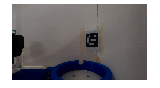

imshow(frame_R)

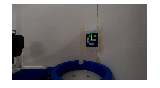

for i = 1:length(poses_R)
  % Get image coordinates for axes
  imagePoints = world2img(worldPoints,poses_R(i),camintrinsics);
 
  axesPoints = [imagePoints(1,:) imagePoints(2,:);
                imagePoints(1,:) imagePoints(3,:);
                imagePoints(1,:) imagePoints(4,:)];
  % Draw colored axes
  frame_R = insertShape(frame_R, "Line", axesPoints, ...
      Color = ["red","green","blue"], LineWidth=10);
end
% Display the results.
imshow(frame_R)

poses_R.A    

ans =     0.7715   -0.0343   -0.6353   33.0242
    0.0079   -0.9980    0.0634   -8.5837
   -0.6362   -0.0539   -0.7696  186.2318
         0         0         0    1.0000


## Left Camera Aruco Detection

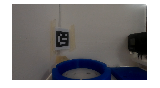

imshow(frame_L)

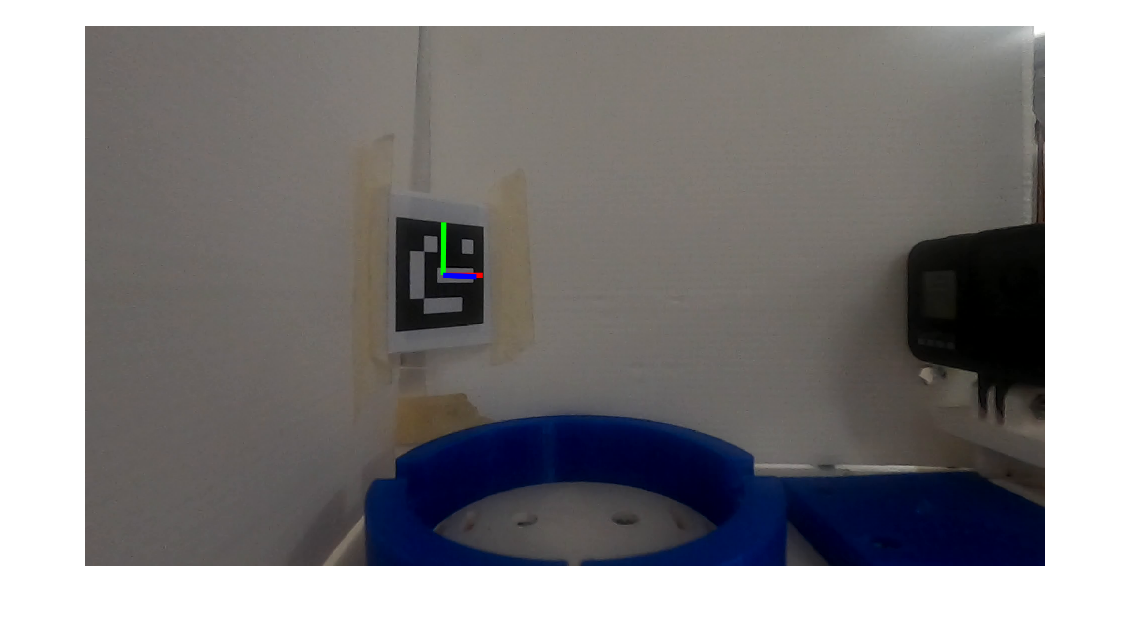

for i = 1:length(poses_L)
  % Get image coordinates for axes
  imagePoints = world2img(worldPoints,poses_L(i),camintrinsics);
 
  axesPoints = [imagePoints(1,:) imagePoints(2,:);
                imagePoints(1,:) imagePoints(3,:);
                imagePoints(1,:) imagePoints(4,:)];
  % Draw colored axes
  frame_L = insertShape(frame_L, "Line", axesPoints, ...
      Color = ["red","green","blue"], LineWidth=10);
end
% Display the results.
imshow(frame_L)

poses_L.A

ans =     0.6370    0.0285    0.7703  -46.4557
   -0.0394   -0.9968    0.0694  -10.9196
    0.7698   -0.0746   -0.6339  172.3992
         0         0         0    1.0000


## Save mat files

if save_mat
    save(save_path, 'poses_L','poses_R');
end